# Example 2: Vertical mast

The wind field is now simulated along a vertical line (e.g. a wind mast). I use the input file INPUT_MAST.txt with 20 nodes created along a vertical line, for altitudes ranging from 10 to 90 m. The power law was chosen for the vertical wind profile. The mean wind velocity at the reference height was: $ $U_ {ref} = 20 $$ m/s, and the reference height was 10 m above the sea.The coefficient for the power law is: *a* = 0.15.

The position of "y" is not important any longer. I have chosen it equal to 0, but it could have been anything else. The new grid is, therefore, defined using:

- Nyy	= 1					(number of nodes along y axe)

- Nzz	= 20					(number of nodes along z axe)

- Zmin = 10				(min altitude of grid for z-axe (meters))

- Zmax = 90				(max altitude of grid for z-axe (meters))

- Ymin = 0					(min longitude for y-axe (meters))

- Ymax = 0					(max longitude for y-axe (meters))

The evolution of the turbulent parameters (Lu,Iu, coherence...) are here defined based on the reference height and reference wind velocity only. In reality, this may be different. In that case, a modification of the function windSim may be required.

## Time series simulation

clearvars;close all;clc;
rng(1) ;% to ensure reproducibility of the example.
filename = 'INPUT_Example2.txt';
[u,v,w,t,nodes] = windSim(filename);

Duration of target time series is 0.569 hours, i.e. 2.05e+03 sec 

Expected computation time: From 20 to 43 seconds 


U = u+nodes.U*ones(size(t)); % get fluctuating + mean value

## Time series overview

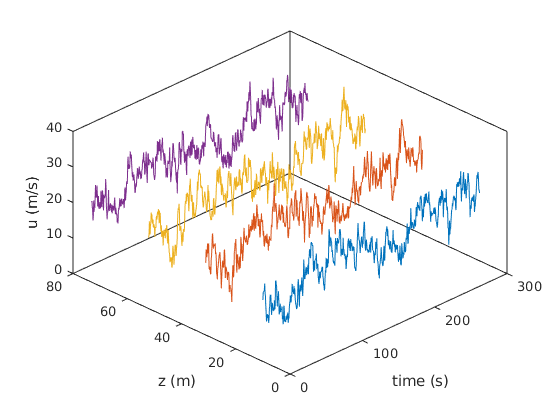

figure
box on; hold on
[x,z]=meshgrid(t(1:600),nodes.Z(1:5:end));
plot3(x',z',U(1:5:end,1:600)')
xlabel('time (s) ');
zlabel('u (m/s)')
ylabel('z (m)')
set(gcf,'color','w')
view(-45,45)

## Vertical mean wind speed profile

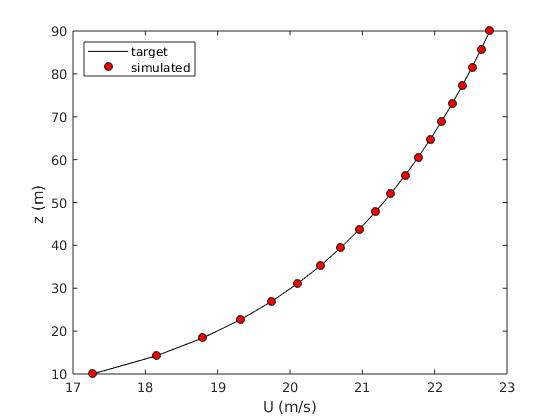

zr = 10; % 10 meters
a = 0.15 ; % cf INPUT_MAST.txt
U_target= nodes.U(1).*(nodes.Z./zr).^(a);
figure
hold on; box on;
plot(mean(U,2),nodes.Z,'k')
plot(nodes.U,nodes.Z,'ko','markerfacecolor','r')
legend('target','simulated','location','NorthWest')
ylabel('z (m) ');
xlabel('U (m/s)')

set(gcf,'color','w')

## Turbulence intensity

The present code specifies a turbulent intensity that decreases for increasing mean wind velocity, i.e. for increasing altitudes. This is more realistic than the constant turbulent intensity introduced in a previous version.

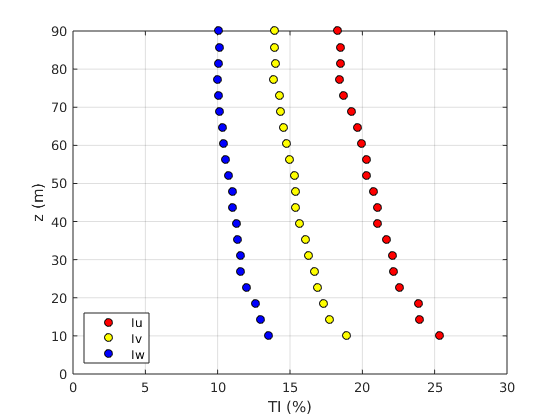

Iu = std(u,0,2)./nodes.U*100;
Iv = std(v,0,2)./nodes.U*100;
Iw = std(w,0,2)./nodes.U*100;

figure
box on;hold on,grid on
plot(Iu,nodes.Z,'ko','markerFaceColor','r')
plot(Iv,nodes.Z,'ko','markerFaceColor','y')
plot(Iw,nodes.Z,'ko','markerFaceColor','b')
ylabel('z (m)')
xlabel('TI (%)')
set(gcf,'color','w')
legend('Iu','Iv','Iw','location','SouthWest')
xlim([0 30])
ylim([0 max(nodes.Z)])

## Co-coherence

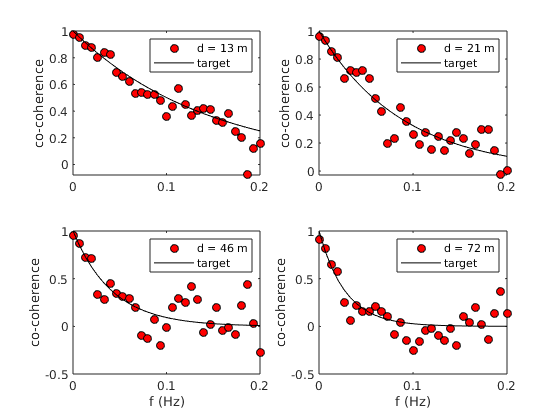

% time step & sampling frequency
dt = median(diff(t));
fs = 1/dt;
tmax = t(end);
f0 = 1/tmax;
[Nsamples,N] = size(u);
% block duration (each)
NBlock = 12;% number of blocks
% number of data point per block
Ncoh = round(N/NBlock);
clear Su Sv Sw

if mod(Ncoh,2)
    cocoh = zeros(Nsamples,Nsamples,round(Ncoh/2));
else
    cocoh = zeros(Nsamples,Nsamples,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function "coherence"
for ii=1:Nsamples
    for jj=1:Nsamples
        [cocoh(ii,jj,:),~,freq] = coherence(u(ii,:),u(jj,:),Ncoh,round(Ncoh/2),Ncoh,fs);
    end
end

dz = abs(nodes.Z-nodes.Z');
meanU_coh = 0.5*(nodes.U +nodes.U');
nodeTarget = [4 6 12 18];

figure
for ii=1:numel(nodeTarget)
    subplot(2,2,ii)
    box on;hold on
    plot(freq,squeeze(cocoh(1,nodeTarget(ii),:)),'ko','markerfacecolor','r');
    plot(freq,exp(-10.*dz(1,nodeTarget(ii)).*freq/meanU_coh(1,nodeTarget(ii))),'k');
    legend(['d = ',num2str(round(abs(nodes.Z(1)-nodes.Z(nodeTarget(ii)))),2),' m'],'target');
    xlim([0,0.2])
    ylabel('co-coherence')
    if ii>2
        xlabel('f (Hz)')
    end
    set(gcf,'color','w')
end